clear
addpath('Assignment 4')
load modl.mat


[num, den] = frsfit(fr_l,hz,[4,1 ,2])

Frequency vector is linear; WF is therefore adjusted.
initial estimate of FRQLS
determination of initial errors
 
Building original data matrix
 
Start output error iterations
OE iteration 1; a/m-re of 1/den: 5.7506 16.7418
OE iteration 2; a/m-re of 1/den: 0.063318 0.22189
OE iteration 3; a/m-re of 1/den: 0.029251 0.095446
OE iteration 4; a/m-re of 1/den: 0.015271 0.047284
OE iteration 5; a/m-re of 1/den: 0.0080645 0.02569
OE iteration 6; a/m-re of 1/den: 0.0042163 0.013606
OE iteration 7; a/m-re of 1/den: 0.0021833 0.0070895
OE iteration 8; a/m-re of 1/den: 0.0011236 0.0036598
OE iteration 9; a/m-re of 1/den: 0.00057626 0.0018799
OE iteration 10; a/m-re of 1/den: 0.00029499 0.00096306
OE iteration 11; a/m-re of 1/den: 0.00015086 0.00049271
OE iteration 12; a/m-re of 1/den: 7.7111e-05 0.00025189
OE iteration 13; a/m-re of 1/den: 3.9404e-05 0.00012873
OE iteration 14; a/m-re of 1/den: 2.0133e-05 6.5779e-05
OE iteration 15; a/m-re of 1/den: 1.0286e-05 3.3608e-05
OE iteration 16; a/m-re o

num =             0            0            0   1.0486e+05   1.6045e+09


den =    1.0000e+00   6.1380e+00   9.3170e+04            0            0



H = tf(num,den)

H =
 
      1.049e05 s + 1.604e09
  ------------------------------
  s^4 + 6.138 s^3 + 9.317e04 s^2
 
Continuous-time transfer function.
Model Properties


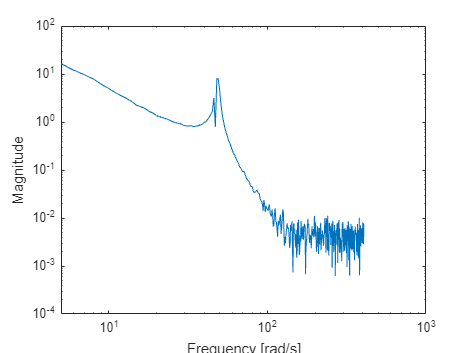



bodeplm(hz,fr_l)

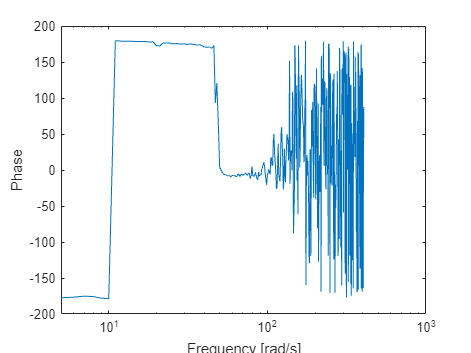

bodeplp(hz,fr_l)

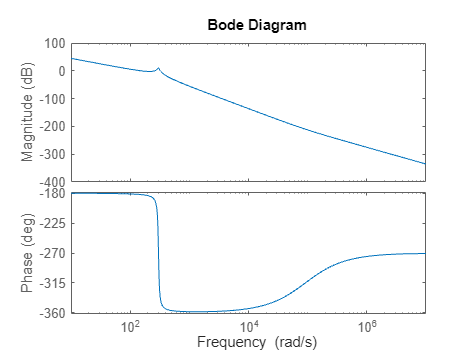


sys = ss(al,bl,cl,dl);
bode(sys)

pole(sys)

ans =    0.0000e+00 + 0.0000e+00i
   0.0000e+00 + 0.0000e+00i
  -8.3550e+00 + 3.0110e+02i
  -8.3550e+00 - 3.0110e+02i


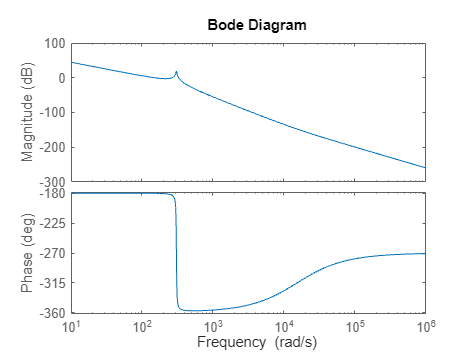

bode(H)

pole(H)

ans =    0.0000e+00 + 0.0000e+00i
   0.0000e+00 + 0.0000e+00i
  -3.0690e+00 + 3.0522e+02i
  -3.0690e+00 - 3.0522e+02i


log(10)

ans =    2.3026e+00
